clear; clc;
bloodHU = xlsread("D:\Senior Design Project\SeniorDesign2022\Sicong\Blood HU data.xlsx");
% 24211 Healthy
ID24211RCA = rmmissing(bloodHU(:,1));
ID24211LAD = rmmissing(bloodHU(:,2));
ID24211LCX = rmmissing(bloodHU(:,3));

% 24319 Healthy
ID24319RCAp = rmmissing(bloodHU(:,4));
ID24319RCAd = rmmissing(bloodHU(:,5));
ID24319LAD = rmmissing(bloodHU(:,6));

% 24384 Healthy
ID24384RCA = rmmissing(bloodHU(:,7));
ID24384LAD = rmmissing(bloodHU(:,8));
ID24384LCX = rmmissing(bloodHU(:,9));

% 24397 Healthy
ID24397RCA = rmmissing(bloodHU(:,10));
ID24397LAD = rmmissing(bloodHU(:,11));

% 24418 Healthy
ID24418RCA = rmmissing(bloodHU(:,12));
ID24418LAD = rmmissing(bloodHU(:,13));

## boxplot for individual segmentations

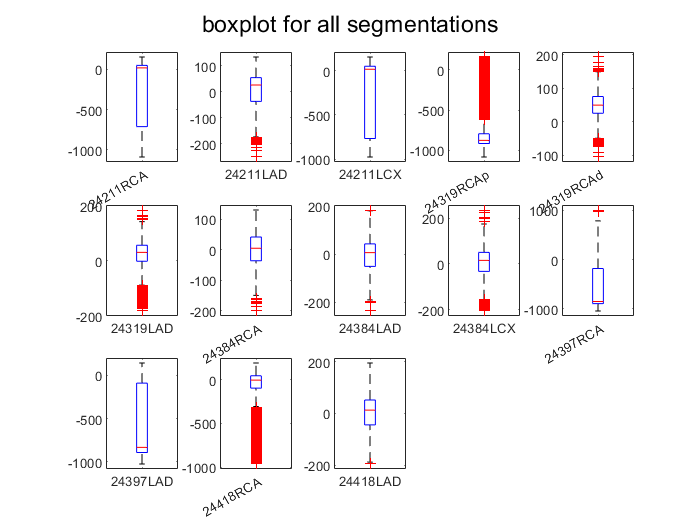

figure;
rawbloodHU = bloodHU;
segmentationNames_all = {'24211RCA','24211LAD','24211LCX',...
    '24319RCAp','24319RCAd','24319LAD',...
    '24384RCA','24384LAD','24384LCX',...
    '24397RCA','24397LAD',...
    '24418RCA','24418LAD'};
figure;
sgtitle('boxplot for all segmentations');
subplot(3,5,1);
boxplot(ID24211RCA,'Labels',segmentationNames_all{1});
subplot(3,5,2);
boxplot(ID24211LAD,'Labels',segmentationNames_all{2});
subplot(3,5,3);
boxplot(ID24211LCX,'Labels',segmentationNames_all{3});
subplot(3,5,4);
boxplot(ID24319RCAp,'Labels',segmentationNames_all{4});
subplot(3,5,5);
boxplot(ID24319RCAd,'Labels',segmentationNames_all{5});
subplot(3,5,6);
boxplot(ID24319LAD,'Labels',segmentationNames_all{6});
subplot(3,5,7);
boxplot(ID24384RCA,'Labels',segmentationNames_all{7});
subplot(3,5,8);
boxplot(ID24384LAD,'Labels',segmentationNames_all{8});
subplot(3,5,9);
boxplot(ID24384LCX,'Labels',segmentationNames_all{9});
subplot(3,5,10);
boxplot(ID24397RCA,'Labels',segmentationNames_all{10});
subplot(3,5,11);
boxplot(ID24397LAD,'Labels',segmentationNames_all{11});
subplot(3,5,12);
boxplot(ID24418RCA,'Labels',segmentationNames_all{12});
subplot(3,5,13);
boxplot(ID24418LAD,'Labels',segmentationNames_all{13});

## Cancelling out outliers

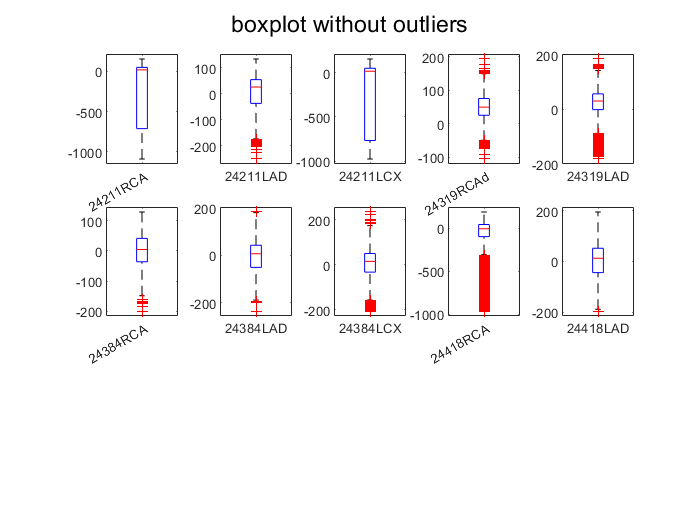

% from the boxplot:
% 1) median: 24319RCAp/24397RCA/24397LAD seems to be outliers, so Sicong
% try to cancel them out
figure;
sgtitle('boxplot without outliers');
subplot(3,5,1);
boxplot(ID24211RCA,'Labels',segmentationNames_all{1});
subplot(3,5,2);
boxplot(ID24211LAD,'Labels',segmentationNames_all{2});
subplot(3,5,3);
boxplot(ID24211LCX,'Labels',segmentationNames_all{3});
% subplot(3,5,4);
% boxplot(ID24319RCAp,'Labels',segmentationNames_all{4});
subplot(3,5,4);
boxplot(ID24319RCAd,'Labels',segmentationNames_all{5});
subplot(3,5,5);
boxplot(ID24319LAD,'Labels',segmentationNames_all{6});
subplot(3,5,6);
boxplot(ID24384RCA,'Labels',segmentationNames_all{7});
subplot(3,5,7);
boxplot(ID24384LAD,'Labels',segmentationNames_all{8});
subplot(3,5,8);
boxplot(ID24384LCX,'Labels',segmentationNames_all{9});
% subplot(3,5,10);
% boxplot(ID24397RCA,'Labels',segmentationNames_all{10});
% subplot(3,5,11);
% boxplot(ID24397LAD,'Labels',segmentationNames_all{11});
subplot(3,5,9);
boxplot(ID24418RCA,'Labels',segmentationNames_all{12});
subplot(3,5,10);
boxplot(ID24418LAD,'Labels',segmentationNames_all{13});

## Median Analysis

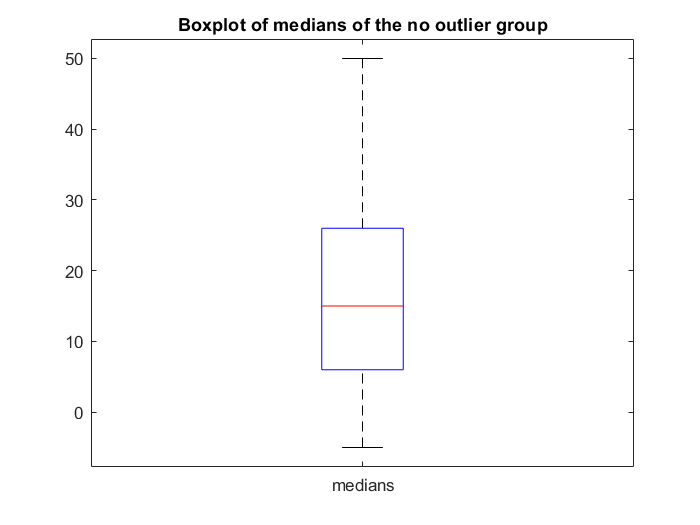

median_of_10_segmentations = [median(ID24211RCA),median(ID24211LAD),median(ID24211LCX),median(ID24319RCAd),median(ID24319LAD),median(ID24384RCA),median(ID24384LAD),median(ID24384LCX),median(ID24418RCA),median(ID24418LAD)];
figure;
boxplot(median_of_10_segmentations,'Labels',"medians");
title('Boxplot of medians of the no outlier group');

% Range of the median HU
maxMedianHU = max(median_of_10_segmentations);
minMedianHU = min(median_of_10_segmentations);
MedianHUrange = [minMedianHU,maxMedianHU]

MedianHUrange =     -5    50


% Quantile of the median HU
lowerQuantile_medianHU = quantile(median_of_10_segmentations,0.25);
upperQuantile_medianHU = quantile(median_of_10_segmentations,0.75);
MedianHUQuantile = [lowerQuantile_medianHU,upperQuantile_medianHU]

MedianHUQuantile =      6    26



% try if the range determination is better or the quantile determination is
% better